%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Cereated by Manishkumar Paghda , 12/01/24
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


clc
clear all
close all


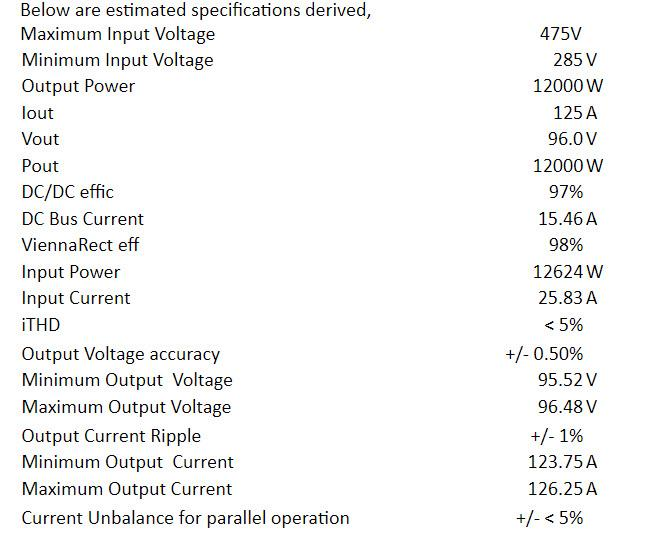

Tsim = 1e-7;

P_out =  12000; %watts

V_out_acdc = 750;
V_in_dcdc = V_out_acdc;
V_out_dcdc = 96;
Imax_out = 126.25*1.05;
Fs =  50000; %switching frequency
Tswitching = 1/Fs;

single_phase = 0;
Unbalance =   1;  %0: balanced 3 pha, 1: Unbalanced 3 ph
harmonics = 1;      % 0: No harmonics in grid, 1: 3rd and 5th harmonics in grid voltage
power_base_control = 2;  %0: current based control, 1:power based control , 2: power and sequence components based control
vdc_fbk_filter = 0;      %0: No notch filter on Vdc feedback
sogi_pr = 1;  %0: cur control PR is non SOGI based , 1: Cur control PR is SOGI based
sfunc_based_con = 0; %0: simlink block  based control, 1: s-function based control

X = 0.3554

acdc = struct with fields:
           Pout: 12000
     Vac_ll_rms: 400
            Fac: 50
            Wac: 314.1593
            Tac: 0.0200
           Vout: 800
           Iout: 15
            Eff: 0.9700
             Fs: 70000
            Tsw: 1.4286e-05
      Tcur_loop: 2.8571e-05
     Tvolt_loop: 2.8571e-05
        Pin_max: 1.8557e+04
             va: 230.9401
             vb: 230.9401
             vc: 184.7521
          va_ph: 0
          vb_ph: -116
          vc_ph: 124
          va_pk: 326.5986
          vb_pk: 326.5986
          vc_pk: 261.2789
      va_ph_rad: 0
      vb_ph_rad: -2.0246
      vc_ph_rad: 2.1642
      va_pk_3rd: 16.3299
      vb_pk_3rd: 16.3299
      vc_pk_3rd: 13.0639
      va_pk_5th: 9.7980
      vb_pk_5th: 9.7980
      vc_pk_5th: 7.8384
            Pin: 1.2371e+04
    Igrid_ph_pk: 25.2525
     cur_ripple: 1.2626
              L: 0.0011
          L_ESR: 0.0468
        Vripple: 8
              C: 1.8375e-04



PR_s =
 
          20 s
  --------------------
  s^2 + 20 s + 9.87e04
 
Continuous-time transfer function.
Model Properties



PR_d =
 
  0.0005713 z - 0.0005713
  -----------------------
  z^2 - 1.999 z + 0.9994
 
Sample time: 2.8571e-05 seconds
Discrete-time transfer function.
Model Properties



notch_d =
 
    z^2 - 1.997 z + 1
  ----------------------
  z^2 - 1.924 z + 0.9267
 
Sample time: 2.8571e-05 seconds
Discrete-time transfer function.
Model Properties


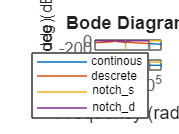

%AC- DC converter design

if single_phase == 1

else
    acdc.Pout =  12000;
    acdc.Vac_ll_rms = 400;
    acdc.Fac = 50;
    acdc.Wac = acdc.Fac*2*pi;
    acdc.Tac = 1/acdc.Fac;
    acdc.Vout = 800;
    acdc.Iout = acdc.Pout/acdc.Vout;
    acdc.Eff = 0.97;
    acdc.Fs = 70000;
    acdc.Tsw = 1/acdc.Fs;
    acdc.Tcur_loop = acdc.Tsw*2;
    acdc.Tvolt_loop = acdc.Tcur_loop;
    acdc.Pin_max = acdc.Pout/acdc.Eff * 1.5;

    if(Unbalance == 0)

        acdc.va = acdc.Vac_ll_rms/sqrt(3);
        acdc.vb = acdc.Vac_ll_rms/sqrt(3);
        acdc.vc = acdc.Vac_ll_rms/sqrt(3);



        acdc.va_ph = 0; 
        acdc.vb_ph = -120; 
        acdc.vc_ph = 120; 

    else

        acdc.va = acdc.Vac_ll_rms/sqrt(3);
        acdc.vb = acdc.Vac_ll_rms/sqrt(3);
        acdc.vc = acdc.Vac_ll_rms/sqrt(3)*0.8;

        acdc.va_ph = 0; 
        acdc.vb_ph = -116; 
        acdc.vc_ph = 124; 

    end
   
        acdc.va_pk = acdc.va *sqrt(2);
        acdc.vb_pk = acdc.vb *sqrt(2);
        acdc.vc_pk = acdc.vc *sqrt(2);

        acdc.va_ph_rad = acdc.va_ph *pi/180;
        acdc.vb_ph_rad = acdc.vb_ph *pi/180;
        acdc.vc_ph_rad = acdc.vc_ph *pi/180;

        if(harmonics == 1)
            acdc.va_pk_3rd= acdc.va_pk *0.05;
            acdc.vb_pk_3rd= acdc.vb_pk *0.05;
            acdc.vc_pk_3rd= acdc.vc_pk *0.05;

            acdc.va_pk_5th= acdc.va_pk *0.03;
            acdc.vb_pk_5th= acdc.vb_pk *0.03;
            acdc.vc_pk_5th= acdc.vc_pk *0.03;

        else

            acdc.va_pk_3rd= 0;
            acdc.vb_pk_3rd= 0;
            acdc.vc_pk_3rd= 0;

            acdc.va_pk_5th= 0;
            acdc.vb_pk_5th= 0;
            acdc.vc_pk_5th= 0;

        end


    acdc.Pin = acdc.Pout/ acdc.Eff;
    acdc.Igrid_ph_pk = sqrt(2)*acdc.Pin/(sqrt(3)*acdc.Vac_ll_rms);
    acdc.cur_ripple = acdc.Igrid_ph_pk*0.05; %  1%

    acdc.L = acdc.Vout/(8*acdc.cur_ripple*acdc.Fs);
    acdc.L_ESR = 0.0468;

    X = (2*pi*50* acdc.L)

    acdc.Vripple = acdc.Vout*0.01; %1 %

%     acdc.C =1/3 *  acdc.Pout/(4*acdc.Fs * (acdc.Vout^2 - (acdc.Vout - acdc.Vripple )^2))
    acdc.C = (acdc.Iout*0.005)*0.98*acdc.Tac/acdc.Vripple
%     acdc.C = (acdc.Iout*0.01)*0.98*acdc.Tac/acdc.Vripple


    acdc.Vac_ph_rms =  acdc.Vac_ll_rms/sqrt(3); %rms
    acdc.Vac_ph_pk = acdc.Vac_ph_rms*sqrt(2);
    
    acdc.Vref = acdc.Vout;

    acdc.Rload = acdc.Vref ^2/acdc.Pout;
    
    
    
    Cur_loop_upper_limit_acdc = acdc.Vout/2;
    acdc.cur_con_sogi_k = 0.06366198;
    
    %PR controller
    wc = 10;
    wo = 2*pi*acdc.Fac;
    PR_s = tf([2*wc,0],[1 2*wc wo^2])
    PR_d = c2d(PR_s,acdc.Tcur_loop)
    [acdc.PR_num,acdc.PR_den] = tfdata(PR_d,'v');

    figure
    bode(PR_s)
    hold on;
    bode(PR_d)
    legend("continous","descrete")

    acdc.cur_con_sogi_k = 2*wc/(acdc.Wac);
    
    %Notch filter for DC bus 2nd harmonics removal purpose
    zeta = 0.707;
    wo_notch = 2*pi*acdc.Fac * 6; %6 times the grid frequncy
    notch_s = tf([1, 0, wo_notch^2],[1 2*zeta*wo_notch wo_notch^2]);
    notch_d = c2d(notch_s,acdc.Tvolt_loop)
    [acdc.notch_num,acdc.notch_den] = tfdata(notch_d,'v');
    
    bode(notch_s)
    hold on;
    bode(notch_d)
    legend("continous","descrete")

    %Controller 
%     acdc.cur_con_kp = 0.1*500 *(1/70000)/acdc.Tcur_loop;
%     acdc.cur_con_ki = 0.6*500 *(1/70000)/acdc.Tcur_loop;

    acdc.cur_con_kp = 0.1*500 ;
    acdc.cur_con_ki = 0.6*500 ;

    %SOGI
    acdc.sogi_k = 0.5;
    acdc.sogi_UL = 500;
    acdc.sogi_LL = -500;
 

    %Unbalance

    if(power_base_control == 0)
        acdc.vdc_kp = 0.5 *(1/70000)/acdc.Tvolt_loop;
        acdc.vdc_ki = 100 *(1/70000)/acdc.Tvolt_loop;

        acdc.vdc_con_max = acdc.Igrid_ph_pk;
        acdc.vdc_con_min = 0;
     
    else

        acdc.vdc_kp = 0.5*400 *(1/70000)/acdc.Tvolt_loop;
        acdc.vdc_ki = 100*400 *(1/70000)/acdc.Tvolt_loop;

        acdc.vdc_con_max =  acdc.Pin_max;
        acdc.vdc_con_min = 0;

    end

    
end

% DC- DC converter design

%inductor design
V_max_out_dcdc = V_out_dcdc*1.2 % 20% margin

V_max_out_dcdc = 115.2000

transformer_turn_ratio = (V_max_out_dcdc)/V_in_dcdc     %max output volt/input volt

transformer_turn_ratio = 0.1536

nominal_duty = V_out_dcdc/V_max_out_dcdc * 1/2          % nominal /max output voltage

nominal_duty = 0.4167

V_Lo = V_in_dcdc * transformer_turn_ratio - V_out_dcdc  %voltage across output inductor

V_Lo = 19.2000


I_out_nom = 125;                         %(max+min)/2
I_out_ripple = I_out_nom * 0.02;  %+/- 1% =  2%
Lo = V_Lo*nominal_duty*Tswitching/(I_out_ripple)

Lo = 6.4000e-05



%capacitor design
V_out_ripple = V_out_dcdc * 0.01;  %+/- 0.5% =  1%

Co = I_out_ripple*nominal_duty*Tswitching/V_out_ripple

Co = 2.1701e-05

%Controller parameters
Volt_loop_upper_limit = Imax_out;
Cur_loop_upper_limit = 180;

PWM_strategy = 0

PWM_strategy = 0

% sim('Vienna_3ph_universal.slx',0.1);

% %Plot
% time =  out.volt_vur_load.Time(:,1);
% skip_data = 1600;
% Tss = time(4) - time(3)
% Skip_sec = 0.04;
% skip_data = int32(Skip_sec/Tss);
% ia_out = out.volt_vur_load.Data(skip_data:end,1);
% Vbus = out.volt_vur_load.Data(skip_data:end,4);
% Vbus_ref = out.volt_vur_load.Data(skip_data:end,5);
% Load = out.volt_vur_load.Data(skip_data:end,6);
% va_out = out.volt_vur_load.Data(skip_data:end,7);
% 
% t = time(skip_data:end);
% figure
% 
% subplot(3,1,1)
% plot(t,acdc.Vref^2./Load);
% grid on;
% legend(["Load"]);
% ylabel("Load (watts)");
% xlabel("time(sec)")
% 
% subplot(3,1,2)
% plot(t,ia_out);
% hold on
% plot(t,va_out/10);
% grid on;
% legend(["Igrid","Vgrid/10"]);
% ylabel("Current(A)");
% xlabel("time(sec)")
% 
% subplot(3,1,3)
% plot(t,Vbus);
% hold on
% plot(t,Vbus_ref);
% grid on;
% legend(["Vbus","Vbus__ref"])
% ylabel("Voltage(V)");
% xlabel("time(sec)")
% % xlim([0.04,0.016]);
% 
% 
% figure
% 
% Skip_sec = 0.08;
% skip_data = int32(Skip_sec/Tss);
% P_in = out.pow_eff.Data(skip_data:end,1);
% P_out = out.pow_eff.Data(skip_data:end,2);
% Eff = out.pow_eff.Data(skip_data:end,3);
% PF = out.pow_eff.Data(skip_data:end,4);
% THD = out.pow_eff.Data(skip_data:end,5);
% t = time(skip_data:end);
% 
% subplot(3,1,1);
% plot(t,P_in);
% hold on
% plot(t,P_out);
% grid on;
% legend(["Input Power","Output Power"])
% ylabel("Power(Watts)");
% xlabel("time(sec)")
% 
% subplot(3,1,2);
% plot(t,Eff);
% % legend(["Efficiency"]);
% % hold on;
% % plot(t,PF);
% grid on;
% legend(["Efficiency"]);
% ylabel("%");
% xlabel("time(sec)")
% 
% subplot(3,1,3);
% % plot(t,Eff);
% % legend(["Efficiency"]);
% % hold on;
% plot(t,PF);
% grid on;
% legend(["Power factor"]);
% ylabel("PF");
% xlabel("time(sec)")
% % 
% % subplot(3,1,3);
% % plot(t,THD);
% % grid on;
% % legend(["Current THD"]);
% 
% % t = 0:0.001:5-0.001;
% % x = 10*sin(2*pi*50*t);
% [mag_one_sided, mag_two_sided, f_one_sided, f_two_sided] = signal_FFT(ia_out,Tss);
% 
% figure
% plot(f_one_sided,abs(mag_one_sided));
% grid on;
% 
% %THD
% Skip_sec = 0.08;
% skip_data = int32(Skip_sec/Tss);
% ia_out = out.volt_vur_load.Data(skip_data:end,1);
% Vbus = out.volt_vur_load.Data(skip_data:end,4);
% % ia_out = out.volt_vur_load.Data(skip_data:end,7);
% L = length(ia_out);
% N = 50;
% 
% ia_long = [];
% 
% for i=1:N
% 
%     ia_long = [ia_long; ia_out];
% end
% 
% T = L*Tss;
% t = 0:Tss:T*N-Tss;
% 
% figure
% subplot(3,1,2)
% plot(Vbus);
% grid on;
% ylabel("Current(A)");
% xlabel("time(sec)");
% 
% [outputSignal, outputSignal_for_ifft,frequency_range,frequency_range_ifft] = signal_FFT(ia_long,Tss);
% mag = abs(outputSignal);
% f_max = frequency_range(end)
% index_h1 = find(mag == max(mag))
% f_h1 = frequency_range(index_h1)
% mag_h1 = mag(index_h1)
% max_har_f = 25*f_h1;
% 
% 
% 
% har_mag = [mag_h1];
% har_freq = [f_h1];
% har = [1];
% 
% for i=3:2:25  %odd harmonics
% 
% f1 = f_h1*i - 0.1*i;
% f2 = f_h1*i + 0.1*i;
% 
% indx1 = find(frequency_range>=f1 &  frequency_range<=f2);
% 
% har_freq = [har_freq f_h1*i];
% har_mag = [har_mag max(mag(indx1))];
% har = [har i];
% 
% end
% 
% figure
% bar(har,har_mag);
% grid on
% 
% THD = sqrt(sum(har_mag(2:end).^2))/har_mag(1)*100
% 
% Vbus_rippl_per = (max(Vbus)- min(Vbus))/mean(Vbus) * 100
% 
% Unbalance
% harmonics
% power_base_control %0: current based control, 1:power based control
% vdc_fbk_filter

parent_dir = pwd;
dir1 = strcat(parent_dir,'\C_Code');
cd(dir1);

Error using cd
Unable to change current folder to 'C:\Users\Manishkumar Dhirajla\OneDrive - Trystar, LLC\Desktop\Simulation\Manish\Sfunction\Vienna\Simulation\C_Code' (Name is nonexistent or not a folder).

headerfiles = strcat(pwd,'\generic\GenericBlocks.h');
headerfiles = {headerfiles, 'Pll.h','VbusController.h','CurRefGen.h','CurController.h'};
Simulink.importExternalCTypes(headerfiles);



def = legacy_code('initialize');

def.SrcPaths = {'generic'};
def.IncPaths = {'generic'};

def.SourceFiles = {'Vienna.c','GenericBlocks.c','Pll.c','VbusController.c','CurRefGen.c','CurController.c'};
def.HeaderFiles = {'Vienna.h','Pll.h'};
def.InitializeConditionsFcnSpec = ['vienna_initialize()'];

def.SFunctionName = 'sfun_pll';
def.OutputFcnSpec = ['sim_pll_calc(ABC_TYPE u1[1], PLL_OUT_TYPE y1[1])'];
legacy_code('generate_for_sim',def);

def.SFunctionName = 'sfun_vbus_con';
def.OutputFcnSpec = ['sim_VbusController_calc(VBUSCONTROLLER_IN_TYPE u1[1], VBUSCONTROLLER_OUT_TYPE y1[1])'];
legacy_code('generate_for_sim',def);

def.SFunctionName = 'sfun_cur_ref_gen';
def.OutputFcnSpec = ['sim_CurRefGen_calc(CURREFGEN_IN_TYPE u1[1], CURREFGEN_OUT_TYPE y1[1])'];
legacy_code('generate_for_sim',def);


def.SFunctionName = 'sfun_cur_con';
def.OutputFcnSpec = ['sim_CurController_calc(CURCONTROLLER_IN_TYPE u1[1], CURCONTROLLER_OUT_TYPE y1[1])'];
legacy_code('generate_for_sim',def);

mexDir = strcat(pwd,'\mex');
%delete old sfun files 
path2sfunfiles = strcat(mexDir,'\sfun_*.*');
delete(path2sfunfiles);

%move new sfun files to mex folder
files = dir('sfun_*.*');
for i = 1:size(files, 1)
    movefile([files(i).name], mexDir);
end

dir1 = strcat(parent_dir,'\Simulation');
cd(dir1);



% mstruct = Simulink.Bus.createMATLABStruct("CURREFGEN_IN_TYPE");